% Paso 1: Pedir los valores de los puntos
n = input('Número de puntos: '); % Número de puntos

X = zeros(n, 1); % Inicializar vector de X
Y = zeros(n, 1); % Inicializar vector de Y

for i = 1:n
    X(i) = input(['X(' num2str(i) '): ']);
    Y(i) = input(['Y(' num2str(i) '): ']);
end

% Paso 2: Calcular las diferencias divididas
% Crear la tabla de diferencias divididas
div_diff = zeros(n, n); % Tabla para diferencias divididas
div_diff(:, 1) = Y; % Primer columna es Y

% Calcular las diferencias divididas
for j = 2:n
    for i = 1:(n-j+1)
        div_diff(i, j) = (div_diff(i+1, j-1) - div_diff(i, j-1)) / (X(i+j-1) - X(i));
    end
end

% Mostrar la tabla de diferencias divididas
disp('Tabla de Diferencias Divididas:');

Tabla de Diferencias Divididas:


disp(div_diff);

    4.0000   -0.3333    2.1667   -0.4861
    3.0000    4.0000   -0.7500         0
   -1.0000    1.7500         0         0
    6.0000         0         0         0




% Paso 3: Construir el polinomio de interpolación de Newton
syms x;
P = div_diff(1, 1); % Inicializar el polinomio con el primer término

for k = 2:n
    term = div_diff(1, k);
    for j = 1:(k-1)
        term = term * (x - X(j));
    end
    P = P + term;
end

% Paso 4: Mostrar el polinomio de interpolación
disp('Polinomio de Interpolación de Newton:');

Polinomio de Interpolación de Newton:


disp(P);

$$\left(\frac{13\,x}{6}+\frac{13}{6}\right)\,\left(x-2\right)-\frac{x}{3}-\left(\frac{35\,x}{72}+\frac{35}{72}\right)\,\left(x-1\right)\,\left(x-2\right)+\frac{11}{3}$$

simplify(P)

$$ans = -\frac{35\,x^{3}}{72}+\frac{113\,x^{2}}{36}-\frac{145\,x}{72}-\frac{59}{36}$$

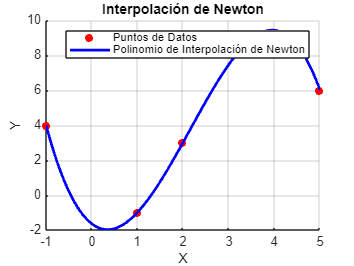


% Paso 5: Evaluar el polinomio en los puntos originales para verificar
Y_hat = double(subs(P, x, X));

% ---------- GRAFICAR RESULTADOS ----------

% Crear una figura
figure;

% Graficar los datos originales
scatter(X, Y, 'ro', 'filled', 'DisplayName', 'Puntos de Datos');
hold on;

% Crear un rango de X para graficar el polinomio de interpolación
X_plot = linspace(min(X), max(X), 100)';
Y_plot = double(subs(P, x, X_plot));

% Graficar la curva del polinomio de interpolación
plot(X_plot, Y_plot, 'b-', 'LineWidth', 2, 'DisplayName', 'Polinomio de Interpolación de Newton');
xlabel('X');
ylabel('Y');
title('Interpolación de Newton');
legend('show');
grid on;